clc; clear all;close all;

%%%%%%          深度学习   %%%%%%%%%%%%%%%
load('E:\毕业设计信号数据\训练深度and迁移学习仿真\训练深度学习\分选\深度\Deep learning True.mat');
Deeplearning_1 = DeeplearningTrue(:,2:end);
Deeplearning_2 = table2array(Deeplearning_1);
dB = Deeplearning_2(1,:);
STFT = Deeplearning_2(2,:);
CWT = Deeplearning_2(3,:);
WVD = Deeplearning_2(4,:);
%%%%%%%%%%  画图  %%%%%%%
figure(1)
plot(dB,STFT,'g * -','LineWidth',1.5)
hold on
plot(dB,CWT,'m square -','LineWidth',1.5)
hold on
plot( dB,WVD,'b diamond -','LineWidth',1.5)
grid on
legend('深度学习 STFT','深度学习 CWT','深度学习 SPWVD', 'Location', 'southeast')
ylabel('准确率');xlabel('信噪比/dB')
title('基于STFT、CWT、SPWVD特征提取的深度学习分选准确率对比')

%%%%%%%%%%%%%%%%%%%%%%      迁移学习     
load('E:\毕业设计信号数据\训练深度and迁移学习仿真\训练深度学习\分选\迁移\Transfer learning True.mat');
Transferlearning_1 = TransferlearningTrue(:,2:end);
Transferlearning_2 = table2array(Transferlearning_1);
dB = Transferlearning_2(1,:);
stft = Transferlearning_2(2,:);
cwt = Transferlearning_2(3,:);
wvd = Transferlearning_2(4,:);
%%%%%%%%%%  画图  %%%%%%%
figure(2)
plot(dB,stft,'c pentagram -','LineWidth',1.5)
hold on
plot(dB,cwt,'y hexagram -','LineWidth',1.5)
hold on
plot( dB,wvd,'r o -','LineWidth',1.5)
legend('Transferlearning STFT','Transferlearning CWT','Transferlearning WVD', 'Location', 'southeast')
xlabel('dB')
grid on
title('Transferlearning 分选')

figure(3)
plot(dB,STFT,'g * -','LineWidth',1.5)
hold on
plot(dB,stft,'c pentagram -','LineWidth',1.5)
legend('Deeplearning STFT','Transferlearning STFT', 'Location', 'southeast')
xlabel('dB')
grid on
title('STFT Deeplearning and Transferlearning contrast')

figure(4)
plot(dB,CWT,'m square -','LineWidth',1.5)
hold on
plot(dB,cwt,'y hexagram -','LineWidth',1.5)
legend('Deeplearning CWT','Transferlearning CWT', 'Location', 'southeast')
xlabel('dB')
grid on
title('CWT Deeplearning and Transferlearning contrast')

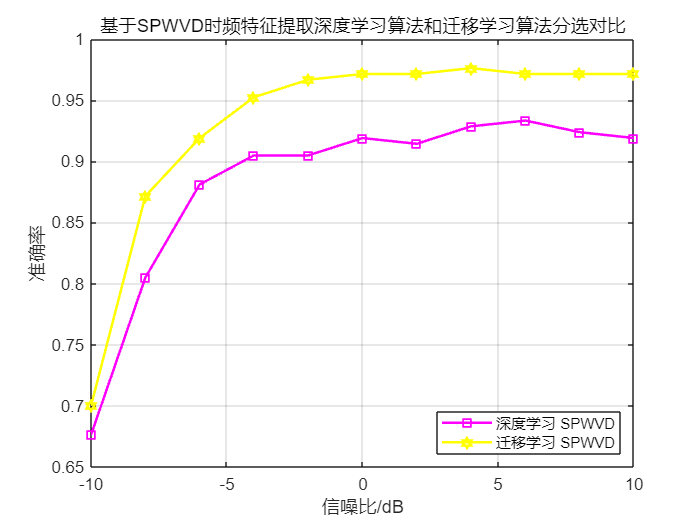

figure(5)
plot(dB,WVD,'m square -','LineWidth',1.5)
hold on
plot(dB,wvd,'y hexagram -','LineWidth',1.5)
legend('深度学习 SPWVD','迁移学习 SPWVD', 'Location', 'southeast')
ylabel('准确率')
xlabel('信噪比/dB')
grid on
title('基于SPWVD时频特征提取深度学习算法和迁移学习算法分选对比')